# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : 

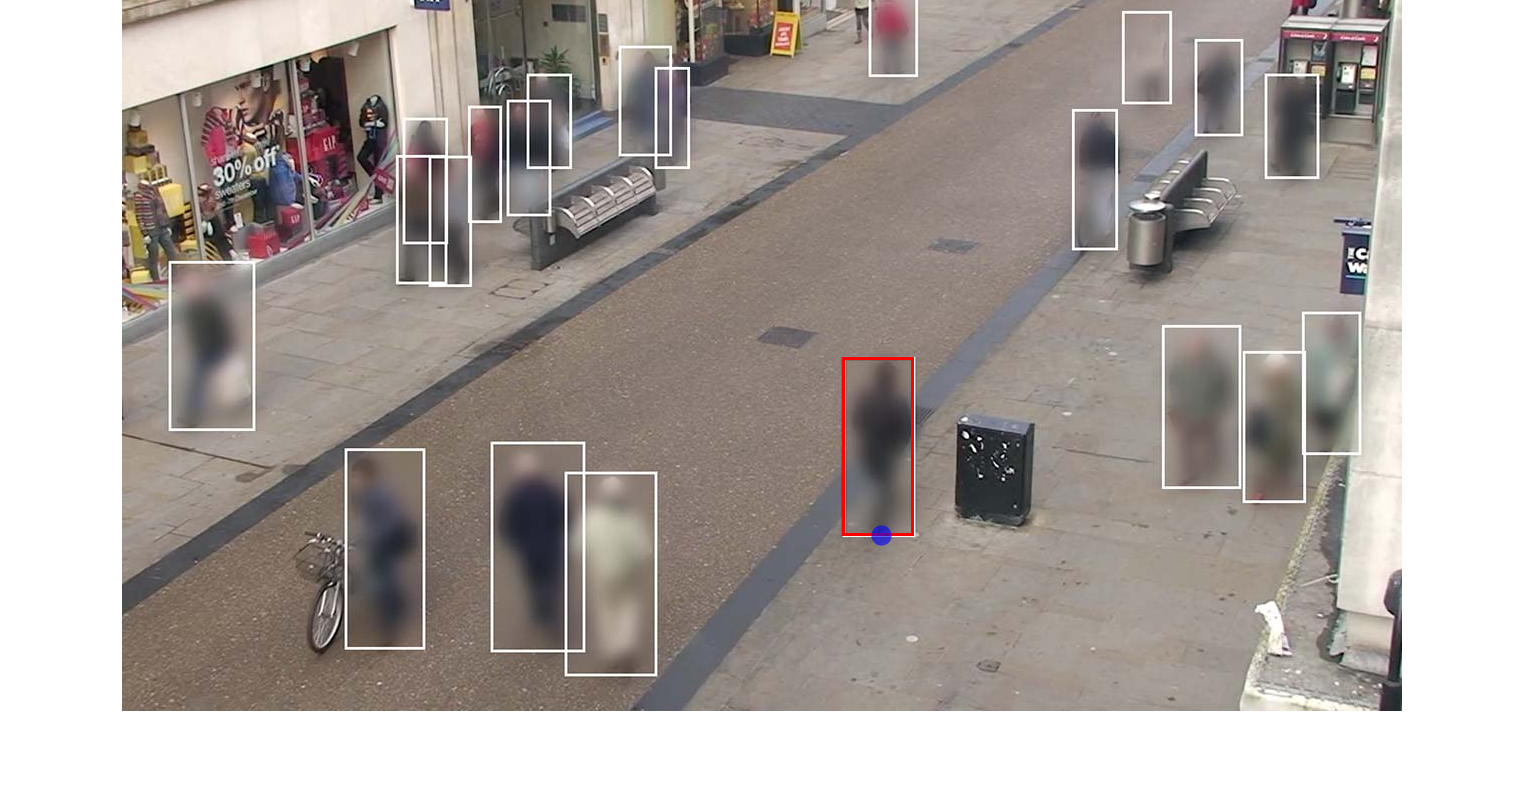

% image 정보 불러오기
img = imread("background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

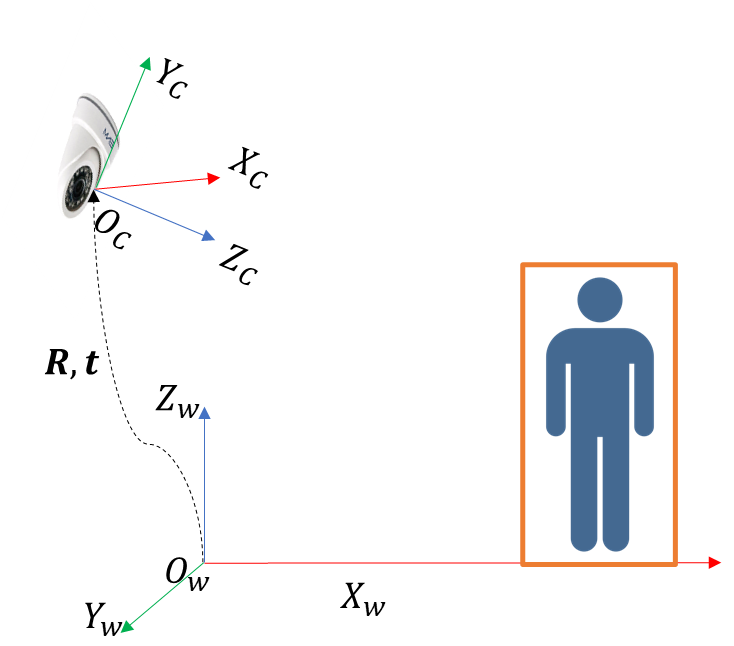

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = pi/2 - pi/6;  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도
% 위치
tx = 0;
ty = -5;
tz = 0.2

tz = 0.2000



% Camera Matrix?
k = [1000 0 640;0 1000 480;0 0 1];

% Rotation Matrix?
Rx = [1 0 0; 0 -0.5 0.866; 0 -0.866 -0.5];
Ry = [0 0 -1; 0 1 0; 1 0 0];
Rz = [0 -1 0; 1 0 0; 0 0 1];

R = Rx*Ry*Rz; % 구한 R 값으로부터 R1,R2,R3을 알 수 있다. 
R

R =          0         0   -1.0000
   -0.5000   -0.8660         0
   -0.8660    0.5000         0


R1 = [0 ;-0.5 ;-0.866];
R2 = [0 ; -0.866 ;0.5];
R3 = [-1 ; 0 ; 0];

% Translation Matrix?
t = [0 ; -5 ; 0.2];

% World Coordinate 좌표 값?

k_=inv(k);

a = [760; 545; 1]; %계산의 편의를 위해 a~a3을 새로 문자로 넣어 코드를 작성했습니다.  
a1 = k_*a;
a2 = [a1,-R1,-R2];
a3 = inv(a2);

ans = a3*t; %최종 구하려는 world coordination, 여기서 Xw = -2.3269 Yw = -4.4302가 된다.
ans 

ans =    -0.0000
   -2.3269
   -4.4302
